# Phys 434 Lab 5

## By Natalie Shen

### Collaborators: Francesca Bennet, Taylor Prewitt

clear all; close all; clc

h5disp("higgs_100000_pt_250_500.h5");

HDF5 higgs_100000_pt_250_500.h5 
Group '/' 
    Dataset 'higgs_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


higg = h5read("higgs_100000_pt_250_500.h5",'/higgs_100000_pt_250_500');

% h5disp("higgs_100000_pt_1000_1200.h5");
% higg2 = h5read("higgs_100000_pt_1000_1200.h5",'/higgs_100000_pt_1000_1200');


h5disp("qcd_100000_pt_250_500.h5");

HDF5 qcd_100000_pt_250_500.h5 
Group '/' 
    Dataset 'qcd_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


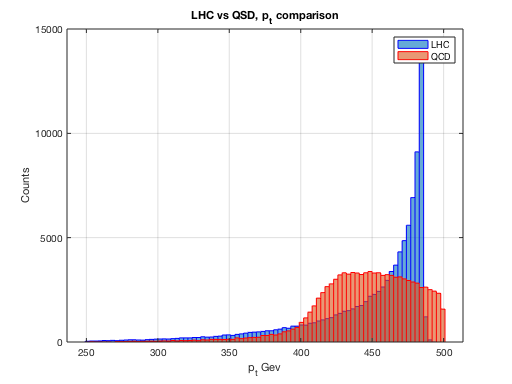

qcd = h5read("qcd_100000_pt_250_500.h5",'/qcd_100000_pt_250_500');

% h5disp("qcd_100000_pt_1000_1200.h5");
% qcd2 = h5read("qcd_100000_pt_1000_1200.h5",'/qcd_100000_pt_1000_1200');

histogram(higg(1,:),"BinMethod","auto","EdgeColor","b")
hold on
grid on
histogram(qcd(1,:), "Binmethod", "auto", "EdgeColor", "r")
hold off
title("LHC vs QSD, p_t comparison");
xlabel("p_t Gev"); ylabel("Counts");
legend("show","LHC","QCD");

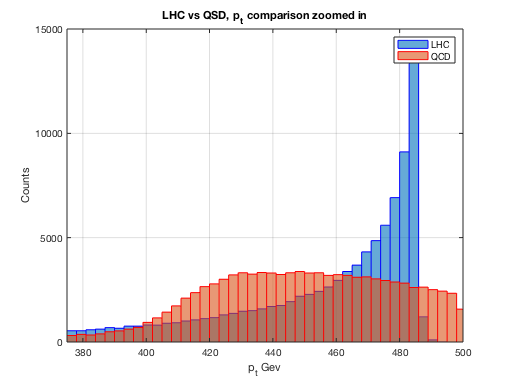


histogram(higg(1,:),"BinMethod","auto","EdgeColor","b")
hold on
grid on
histogram(qcd(1,:), "Binmethod", "auto", "EdgeColor", "r")
hold off
title("LHC vs QSD, p_t comparison zoomed in");
xlabel("p_t Gev"); ylabel("Counts");
legend("show","LHC","QCD");
xlim([375,500]);

We can see that LHC has a curved spike at the end while QCD merely jumps upwards earlier than LHC before slowly decreasing. 

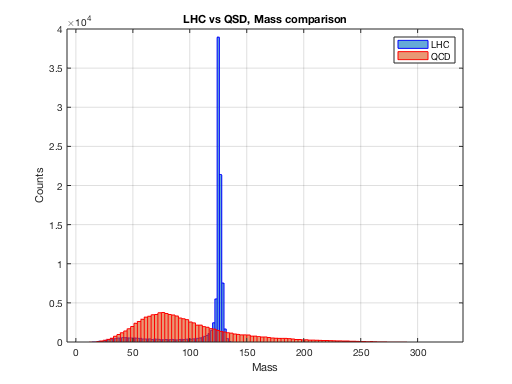

% histogram(higg(2,:),"BinMethod","auto","EdgeColor","b")
% hold on
% histogram(qcd(2,:), "Binmethod", "auto", "EdgeColor", "r")
% hold off
% 
% histogram(higg(3,:),"BinMethod","auto","EdgeColor","b")
% hold on
% histogram(qcd(3,:), "Binmethod", "auto", "EdgeColor", "r")
% hold off

histogram(higg(4,:),"BinMethod","auto","EdgeColor","b")
hold on
grid on
histogram(qcd(4,:), "Binmethod", "auto", "EdgeColor", "r")
hold off
title("LHC vs QSD, Mass comparison");
xlabel("Mass"); ylabel("Counts");
legend("show","LHC","QCD");

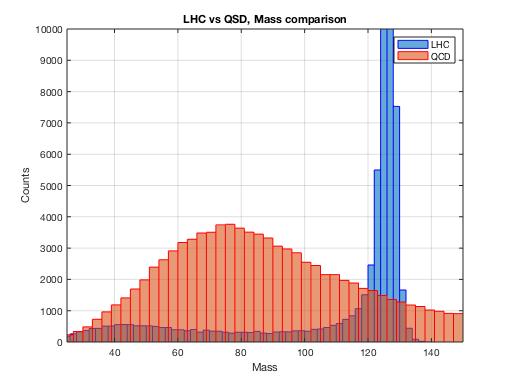


histogram(higg(4,:),"BinMethod","auto","EdgeColor","b")
hold on
grid on
histogram(qcd(4,:), "Binmethod", "auto", "EdgeColor", "r")
hold off
title("LHC vs QSD, Mass comparison zoomed in");
xlabel("Mass"); ylabel("Counts");
legend("show","LHC","QCD");
xlim([25,150]); ylim([0,10^4]);

Though this occurs earlier in the graph, we can see a similar shape as that of pt where LHC has a massive spike and QCD merely rises somewhat before tappering off.

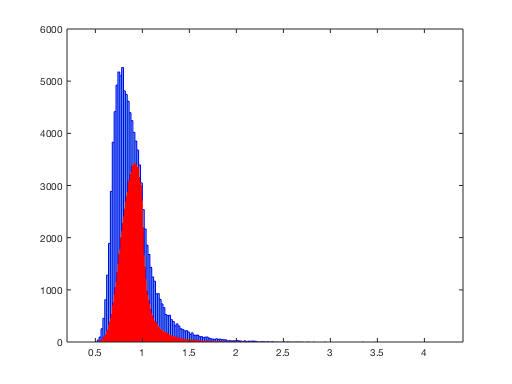

% histogram(higg(5,:),"BinMethod","auto","EdgeColor","b")
% hold on
% histogram(qcd(5,:), "Binmethod", "auto", "EdgeColor", "r")
% hold off
% 
% histogram(higg(6,:),"BinMethod","auto","EdgeColor","b")
% hold on
% histogram(qcd(6,:), "Binmethod", "auto", "EdgeColor", "r")
% hold off
% 
% histogram(higg(7,:),"BinMethod","auto","EdgeColor","b")
% hold on
% histogram(qcd(7,:), "Binmethod", "auto", "EdgeColor", "r")
% hold off
% 
% histogram(higg(8,:),"BinMethod","auto","EdgeColor","b")
% hold on
% histogram(qcd(8,:), "Binmethod", "auto", "EdgeColor", "r")
% hold off

histogram(higg(9,:),"BinMethod","auto","EdgeColor","b")
hold on
grid on
histogram(qcd(9,:), "Binmethod", "auto", "EdgeColor", "r")
hold off

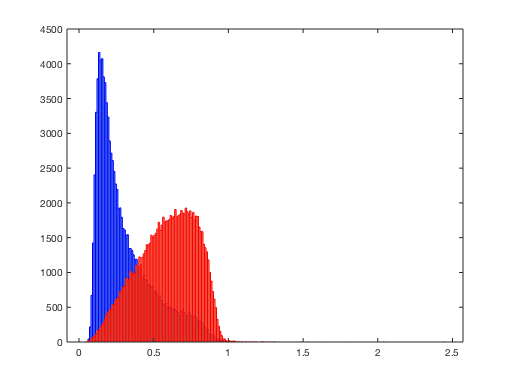

title("LHC vs QSD, T1");
xlabel("T1"); ylabel("Counts");
legend("show","LHC","QCD");

histogram(higg(10,:),"BinMethod","auto","EdgeColor","b")
hold on
grid on
histogram(qcd(10,:), "Binmethod", "auto", "EdgeColor", "r")
hold off

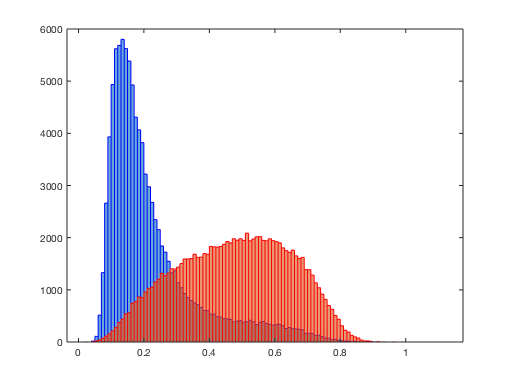

title("LHC vs QSD, T2");
xlabel("T2"); ylabel("Counts");
legend("show","LHC","QCD");

histogram(higg(11,:),"BinMethod","auto","EdgeColor","b")
hold on
grid on
histogram(qcd(11,:), "Binmethod", "auto", "EdgeColor", "r")
hold off

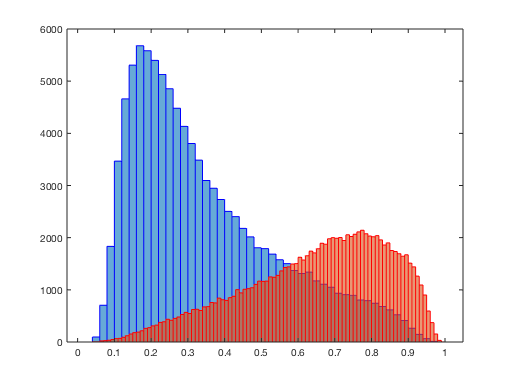

title("LHC vs QSD, T3");
xlabel("T3"); ylabel("Counts");
legend("show","LHC","QCD");

histogram(higg(12,:),"BinMethod","auto","EdgeColor","b")
hold on
grid on
histogram(qcd(12,:), "Binmethod", "auto", "EdgeColor", "r")
hold off

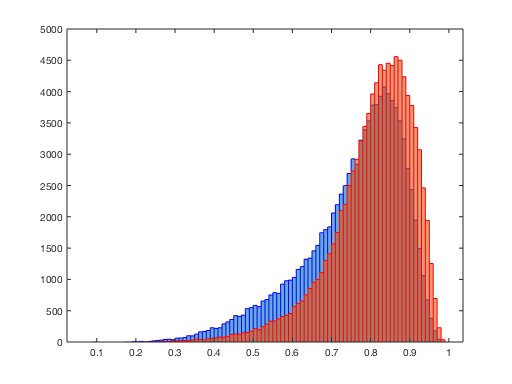

title("LHC vs QSD, T21");
xlabel("T21"); ylabel("Counts");
legend("show","LHC","QCD");

histogram(higg(13,:),"BinMethod","auto","EdgeColor","b")
hold on
grid on
histogram(qcd(13,:), "Binmethod", "auto", "EdgeColor", "r")
hold off

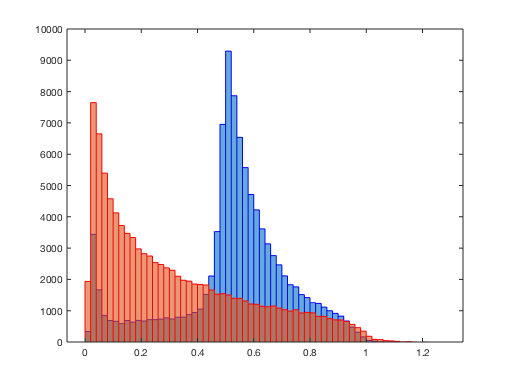

title("LHC vs QSD, T32");
xlabel("T32"); ylabel("Counts");
legend("show","LHC","QCD");

histogram(higg(14,:),"BinMethod","auto","EdgeColor","b")
hold on
grid on
histogram(qcd(14,:), "Binmethod", "auto", "EdgeColor", "r")
hold off

title("LHC vs QSD, KtDeltaR");
xlabel("KtDeltaR"); ylabel("Counts");
legend("show","LHC","QCD");

T1, T2, T3 and T21 show similar shape but it seems more and more zoomed in as we progress.

T32 seems to be the strangest out of the bunch where both LHC and QSD are almost identical.

KtDeltaR seems to follow T32's trend of identical graphs however the positions are different and LHC has a weird spike at the beginning